-     Implementación de todos los modos de comunicación de PRIME en el caso de canal sin distorsión y sin FEC 

Parámetros

format compact; clear all; close all;
NFFT=512; % tamaño FFT
Ncp=48; % tamaño prefijo ciclico
Fs=250*10^3; % F muestreo
Ts=1/Fs; % T muestreo
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % separacion entre f portadoras
R=1/2; %Convolutional coding rate
% secuencia PRBS tamaño 127. se va utilizar 
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];


Trama tiene que durar <= 100 ms. Calculamos Nofdm del payload, ya que conocemos Tsimb.

Tmax=100*10^-3; %segundos
Nofdm= floor(Tmax/(Tsimb)); %M (hacia abajo)

nº bits,  BER fiables inferiores 10^-4. Ber= Perror entre bits RX y bits TX, como "sensibilidad". Si tenemos 10 simbolos transmitidos, BER fiable (minima)= 1/10. Si necesitamos BER=10^-4, bits tx>=10^4.

Ponemos *6 para que el Nbits por trama sea un múltiplo de las 3 m-ary (1,2,3)

Nc= 96;
m_ary=[2 4 8];
m_dpsk=log2(m_ary);
Nbits = Nc*lcm(2,3)*Nofdm;

nº de tramas payload total tx/bits/trama

N_tramas_DPSK=Nbits./(Nofdm*Nc*m_dpsk);
Nbits_trama_DPSK= Nbits./N_tramas_DPSK;

Modular y Aleatorizacion 

txbits = randi(2,1,Nbits)-1;
% modulacion, fase de rotacion inicialmente a 0. modulacion absoluta
%x_tx
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

Demodular y Desaleatorizacion. 

%rxbits

rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

Comparativa BERs teóricas frente a simuladas

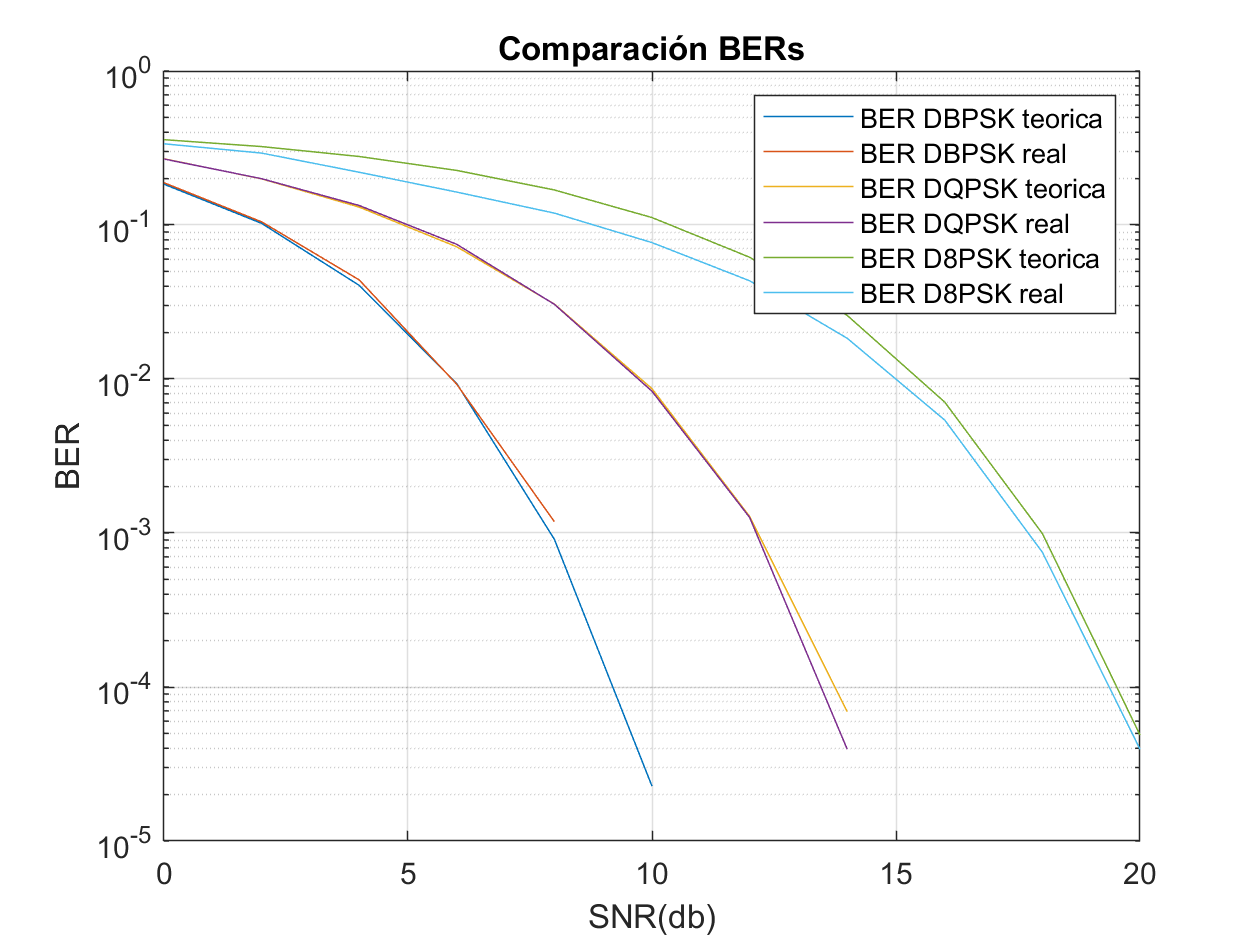

%canal h[n]=1. No hay atenuacion ni retardo en la señal TX producida por el
%canal. Solamente se añade AWGN.
% vector SNR
SNR_db = 0:2:35;
 % Cálculo del factor de ancho de banda . solo distribuir SNR en la parte
 % del espectro con portadoras (Nc)
 fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;
  
%bucle calculo BER_real_DBPSK
    for k=1:length(SNR_db)
        %y_noise=zeros(1, length(x_tx_DBPSK));
       y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
       y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
       y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
       
        y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
                
       
        diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
        diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
        diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
        
        BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
        BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
           
        BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
        BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
        
        BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
        BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
    end
    
%Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

D8PSK + BER CONSTELACION PUNTOS MAS JUNTOS.

        2.   Inclusión de modelo de canal e inclusión de ecualizador

%canal variante en f. Corresponde a un filtro digital de k=9 posiciones en total (en el dominio del tiempo
% discreto):
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1]; % h=[a0...a8]; atenuaciones

   h[n] produce atenuación y retardo por reflexiones dentro de un canal multipath (retardo máximo 8) en la señal a transmitir.

s(t) -> TX

y(t)-> RX

y(t)=conv(s(t),h(t)) -> dominio discreto -> y[n]= conv(s[n],h[n]). 

y[n]=sum(att*s[n-k])- Seguir con esto en latex

H(f) en dbW

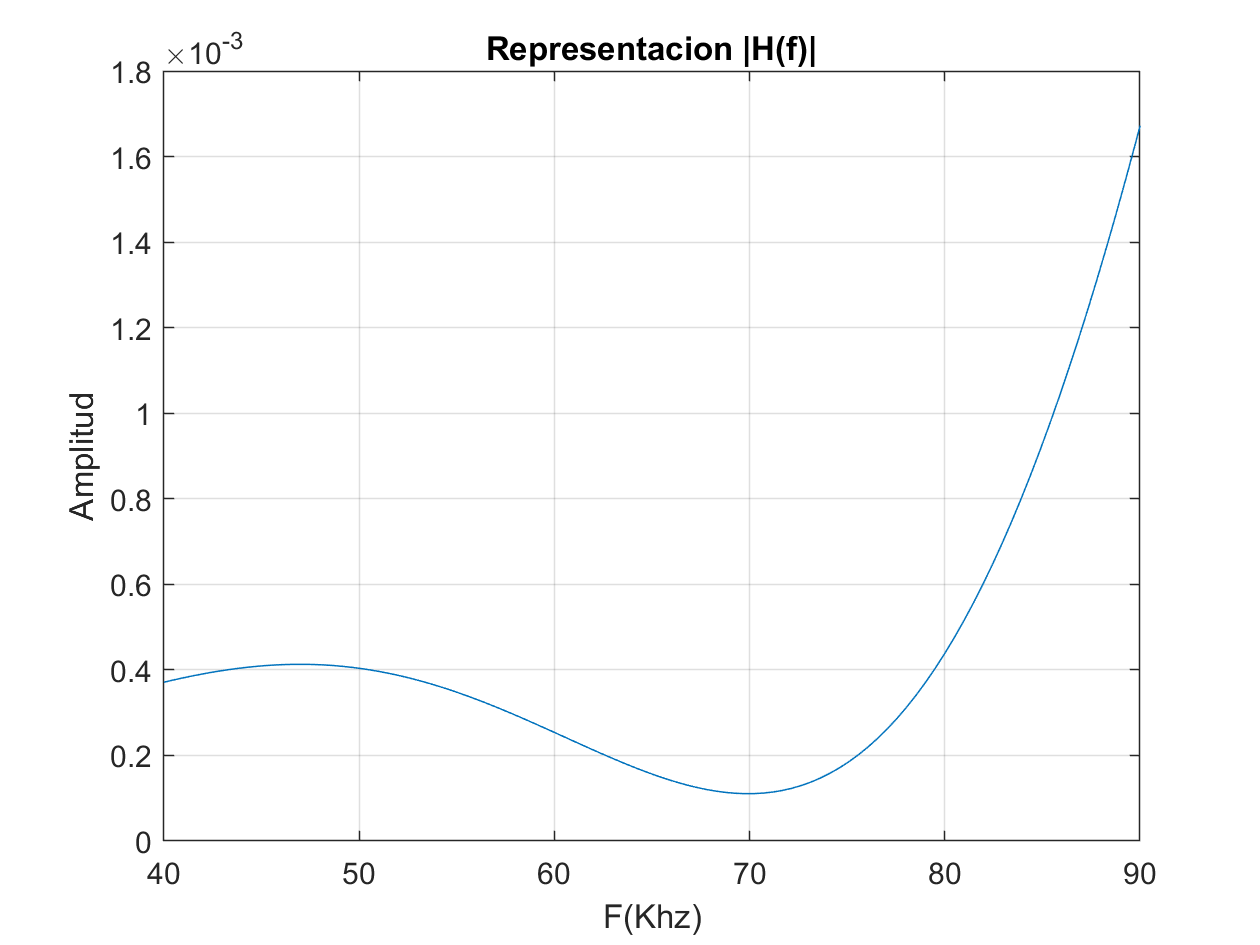

% vector f (paso Fs) -> mitad puntos NFFT espectro + y mitad -. Preguntar

% H(f) es la respuesta al impulso del canal -> FFT.
H=fft(h,NFFT)/NFFT;
f=linspace(-Fs/2,Fs/2, length(H));

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

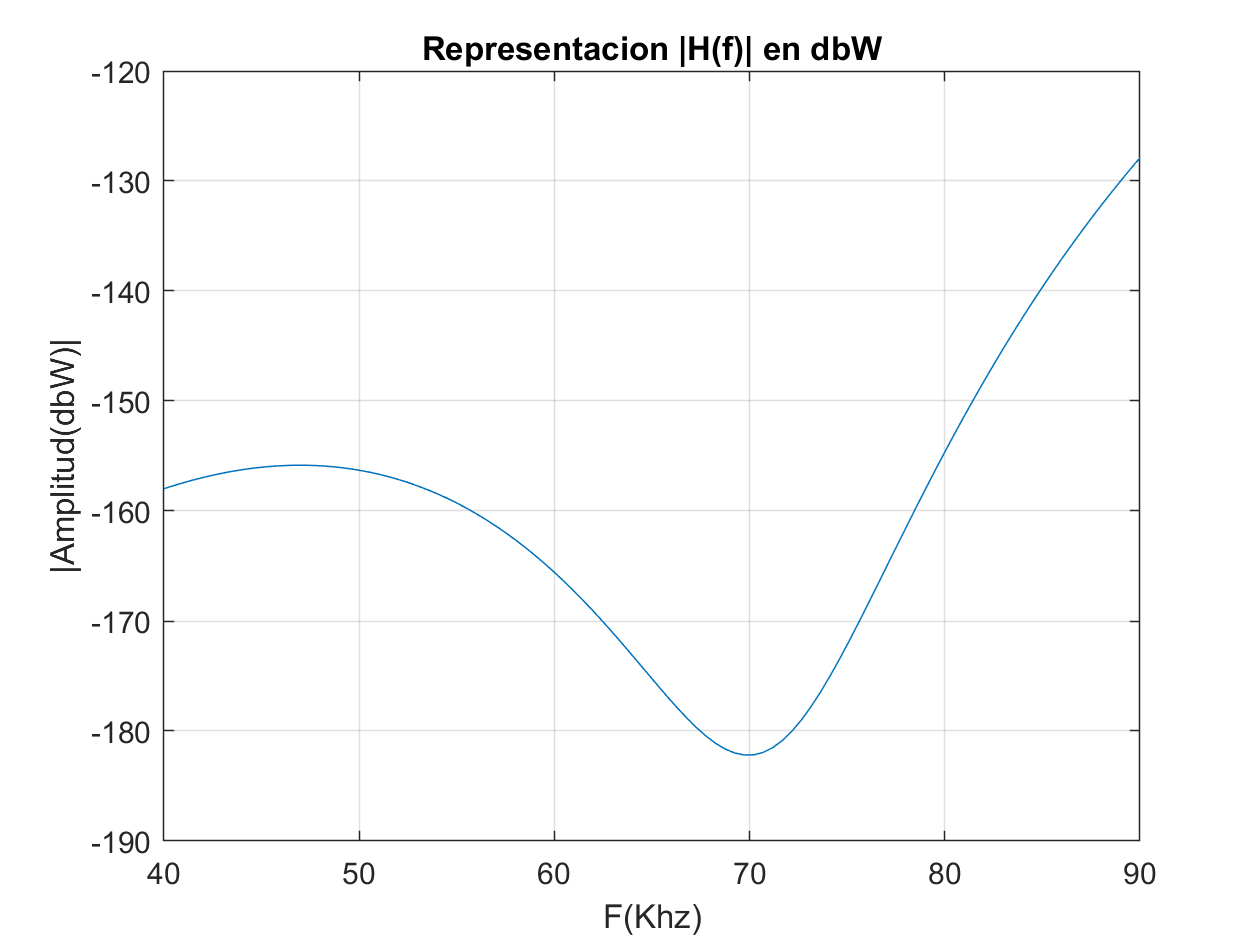

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

%convolucion lineal sin cp y añadimos awgn
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1)

y_canal_DBPSK =    -1.0000    3.2643   -5.3576    6.8319   -7.5627    2.8273    3.0843   -4.4818    3.2440   -0.6799   -4.4768    6.3768   -0.1757   -5.9124    4.3257   -0.2991   -2.2248    5.0277   -3.9153   -3.1526    6.6224   -2.2618   -2.3816    4.0745   -4.0925    0.0398    5.6112   -4.8937   -1.0600    4.2933   -3.5557    1.4151    2.5136   -5.7920    2.8346    3.9541   -5.8423    1.7728    2.5620   -4.7189    3.5534    1.6720   -5.6814    3.5681    1.5882   -4.8944    3.8034    1.1334   -4.2044    2.8064


y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1)

y_canal_DQPSK =     0.6000   -2.5163    5.1428   -6.9026    6.9505   -4.0659   -0.1299    2.9300   -3.1983    0.3334    3.5753   -3.2080   -0.3893    1.5650   -2.0282    2.9009    0.8435   -4.8601    1.8878    1.7419   -2.1835    3.5343   -0.8854   -6.0826    4.2379    4.1131   -4.2986   -0.1940    0.6228   -1.7095    3.8027    0.0035   -5.2480    3.1947    2.4083   -4.0559    2.3622    0.8192   -4.9153    3.9813    3.1162   -5.5546    0.9333    1.8449   -3.0409    3.7876    1.5688   -5.8159    0.8210    2.5692



y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1)

y_canal_D8PSK =    -0.4343    1.1295   -0.5493   -0.3862   -0.5079   -0.0166    1.1283    1.6096   -0.9326   -2.5538   -0.1586    2.2955    0.5826    1.1390   -2.3341   -4.6612    4.7206    5.0183   -4.3518   -3.3467    0.3012    2.9971    3.7080   -4.0519   -4.0444    3.1844    2.0937    0.6777   -1.9133   -3.6351    3.8943    1.8357   -3.9332    2.6309   -0.2627   -3.8577    4.8287   -0.0120   -4.1846    4.0135   -1.3766   -2.9014    5.5448   -1.6911   -3.9420    3.3353   -0.3944    0.4784    1.4032   -4.7069


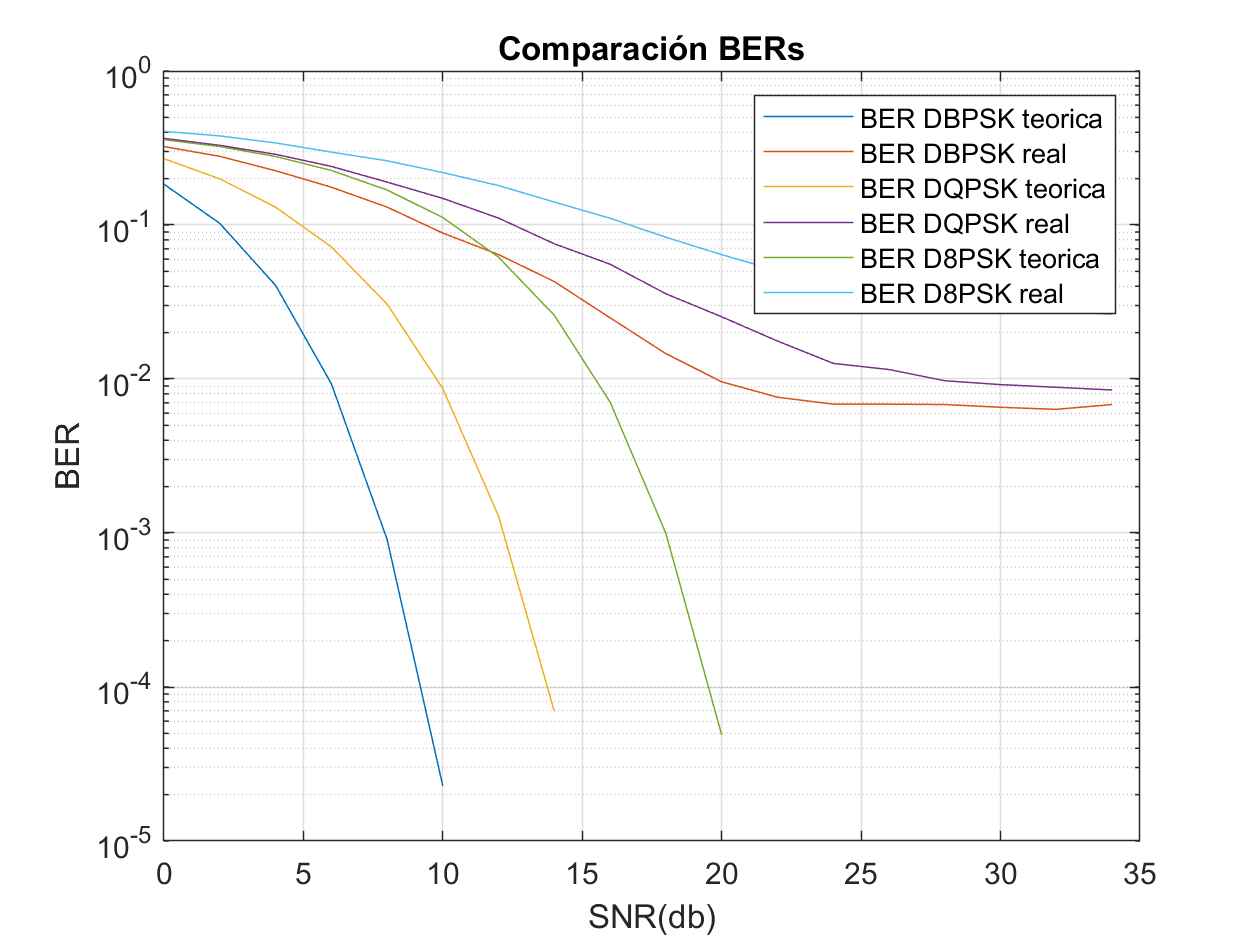

%añadimos el ruido
 for k=1:length(SNR_db)
        %y_noise=zeros(1, length(x_tx_DBPSK));
       y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
       y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
       y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
       
        y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
                
       
        diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
        diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
        diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
        
        BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
        BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
           
        BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
        BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
        
        BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
        BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
 end
 
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

FONDO DE BER EN TORNO 10^-2. eq lo quitara. BPSK MENOR BER

%incluir prefijo ciclico ncp=48. asi se puede recuperar el canal con la
%inversa (problema FFT)
%vectores extendidos
x_tx_DBPSK_cp= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_DQPSK_cp= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_D8PSK_cp= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp);

%receptor sin ruido ni canal para ver que nos quita bien el prefijo

y_rx_DBPSK_cp=receptor(x_tx_DBPSK_cp, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_DQPSK_cp=receptor(x_tx_DQPSK_cp, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_D8PSK_cp=receptor(x_tx_D8PSK_cp, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);

error_dbpsk = sum(abs(txbits-y_rx_DBPSK_cp))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-y_rx_DQPSK_cp))

error_dQpsk = 0

error_d8psk = sum(abs(txbits-y_rx_D8PSK_cp))

error_d8psk = 0